# Principal Component Analysis (PCA)

Lorem Ipsum

⚠️ Work in progress 

clc
clear
close all

## Building dataset

Genero distribuzione normale di $n$ punti random con deviazione standard $\sigma$ e media $\mu$. 

In `MATLAB` è possibile generare delle distribuzioni normali utilizzando la funzione `randn();` tale funzione restituisce una distribuzione centrata sullo zero ($\mu = 0$) e deviazione standard unitaria ($\sigma=1$). Qualora si volessero modificare tali parametri sarà sufficiente moltiplicare l'output per la $\sigma$ voluta e aggiungere $\mu$ al risultato del prodotto. La sintassi sarà quindi del tipo `data = sigma.*randn(n,2) + mu`. Si noti che il numero `2` come argomento della funzione `randn()` indica il numero di colonne da generare: una per le ascisse $x$, una per le ordinate $y$.

Nel caso in cui si volesse specificare una deviazione standard differente per le $x$ e per le $y$ per modificare la forma della distribuzione, è possibile porre $\sigma = ( \sigma_x , \sigma_y)$.

In tal modo, se $P$ è la matrice output della funzione `randn()` 


$$P=\pmatrix{x_1 & y_1 \cr x_2 & y_2 \cr ... & ... \cr  x_n & y_n}$$


sarà sufficiente effettuare moltiplicazione elemen-wise (prodotto di Hadamard) $\sigma \odot P$ per modificare la deviazione standard della distribuzione:


$$\sigma \odot P = \pmatrix{\sigma_x & \sigma_y} \odot \pmatrix{x_1 & y_1 \cr x_2 & y_2 \cr ... & ... \cr  x_n & y_n} =\pmatrix{ \sigma_x x_1 & \sigma_y y_1 \cr \sigma_x x_2  & \sigma_y y_2 \cr ... & ... \cr  \sigma_x x_n & \sigma_y y_n}$$


In `MATLAB` la sintassi da utilizzare è `sigma.*randn(n,2)` dove `sigma = [2 0.9]` con $\sigma_x = 2$, $\sigma_y = 0.9$.

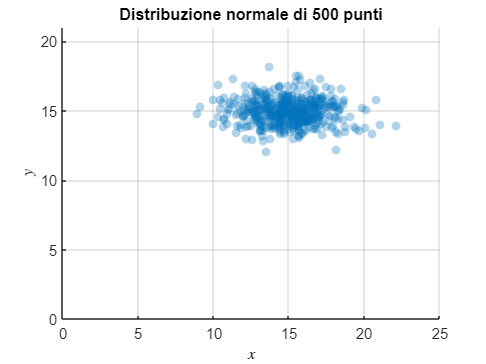

n = 500;                % numero di punti
sigma = [2 0.9];        % deviazione standard su x e su y
mu = 15;                % media

% genero set di dati
data = sigma.*randn(n,2) + mu;

x = data(:,1);
y = data(:,2);

endpoints = find_endpoints(data,2);     % limiti degli assi
alpha = .3;                             % opacità dei punti

% rappresento distribuzione
figure;
scatter(x,y,'o','filled','MarkerEdgeColor','none','MarkerFaceAlpha',alpha)
xlim([0 endpoints(2)])
ylim([0 endpoints(4)])
xlabel("$x$",'Interpreter','latex')
ylabel("$y$",'Interpreter','latex')
title(sprintf("Distribuzione normale di %d punti",n))
grid on
box off
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';

Adesso applichiamo una **trasformazione lineare** alle distribuzioni dei dati. Se la matrice della trasformazione $T$ è


$$T=\pmatrix{1 & 1 \cr -1 & 1}$$


e il dataset contiene gli $n$ punti $P$


$$P=\pmatrix{x_1 & y_1 \cr x_2 & y_2 \cr ... & ... \cr  x_n & y_n}$$


allora i punti trasformati $P'$ si otterranno eseguendo il prodotto matriciale $T P^T$ dove $P^T$ indica la trasposta di $P$


$$P' =T P^T= \pmatrix{1 & 1 \cr -1 & 1} \pmatrix{x_1 & x_2 & ... & x_n \cr y_1 & y_2 & ... & y_n}$$


% creo matrice trasformazione
% linear_trasformation = [1 1; -1 1]
linear_trasformation = rand(2,2)

linear_trasformation =     0.6401    0.0451
    0.1806    0.7232



% applico trasformazione
transformed_data = (linear_trasformation*(data'))'

transformed_data =    10.9626   13.6991
   12.6617   14.8041
    7.3931   12.8604
   11.3931   14.0576
   10.6902   13.7455
    8.6212   13.3708
    9.7265   13.4664
   10.8292   15.4948
   14.8114   14.0902
   13.7479   13.3504


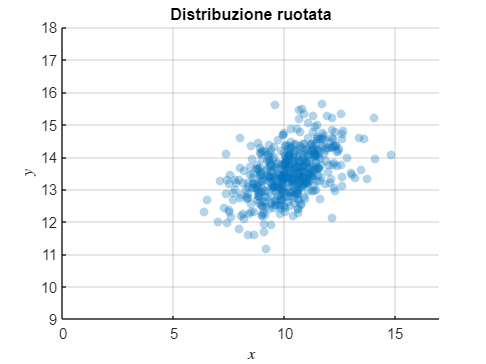


x = transformed_data(:,1);
y = transformed_data(:,2);

endpoints = find_endpoints(transformed_data,2);     % limiti degli assi

% rappresento distribuzione ruotata
scatter(x,y,'o','filled','MarkerEdgeColor','none','MarkerFaceAlpha',alpha)
xlim([0 endpoints(2)])
ylim([endpoints(3) endpoints(4)])
xlabel("$x$",'Interpreter','latex')
ylabel("$y$",'Interpreter','latex')
grid on
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
title("Distribuzione ruotata")

## Centering data

% centro i dati sottraendo la media
dfm = mean(transformed_data)

dfm =    10.2477   13.5207


B = transformed_data-dfm

B =     0.7149    0.1784
    2.4141    1.2834
   -2.8546   -0.6603
    1.1454    0.5368
    0.4425    0.2248
   -1.6265   -0.1499
   -0.5212   -0.0543
    0.5815    1.9741
    4.5637    0.5694
    3.5002   -0.1703


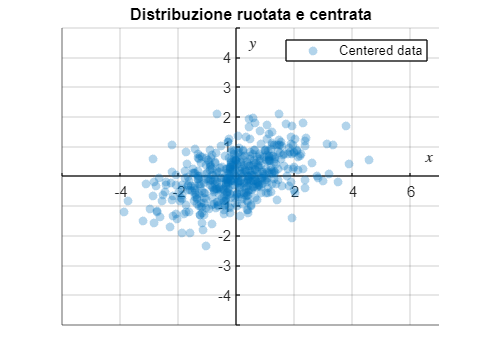


% rappresento distribuzioni centrate
scatter(B(:,1),B(:,2), 'filled', 'MarkerFaceAlpha', alpha,'MarkerEdgeColor','none')
title("Distribuzione ruotata e centrata")
xlabel("$x$",'Interpreter','latex')
ylabel("$y$",'Interpreter','latex')
legend("Centered data")
axis(find_endpoints(B,2))
box off
grid on
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';

## Ricerca dei PC

I *Principal components* sono degli assi su cui è possibile proiettare i dati massimizzando la varianza. Tali assi sono definiti come gli **autovettori** della **matrice di covarianza** $\Sigma$


$$\Sigma = \pmatrix{var(\bar{x}) & cov(\bar{x},\bar{y}) \cr cov(\bar{y},\bar{x}) & var(\bar{y})}$$


In `MATLAB` è possibile determinare gli autovettori e gli autovalori di una matrice S utilizzando la sintassi `[autovettori, autovalori] = eig(S)` dove `C` è la matrice di covarianza. Noi saremo interessati all'autovalore massimo (che sarà utile per PC1).

% determino matrice di covarianza
S = cov(B)

S =     1.6472    0.4410
    0.4410    0.5224



% calcolo autovettori e autovalori di S
[evecs,evals]=eig(S)

evecs =     0.3264   -0.9452
   -0.9452   -0.3264


evals =     0.3701         0
         0    1.7994



% individuo autovalore massimo nella diagonale di evals
[eval_max,id_eval_emax]= max(diag(evals));


% estraggo la colonna id_eval_max dalla matrice evecs per ottenere
% l'autovettore PC1
PC1 = evecs(:,id_eval_emax)

PC1 =    -0.9452
   -0.3264



% proiettiamo i dati B su PC1 eseguendo il prodotto scalare
z = B*PC1

z =    -0.7340
   -2.7007
    2.9138
   -1.2579
   -0.4916
    1.5863
    0.5103
   -1.1939
   -4.4996
   -3.2529



% otteniamo coordinate delle proiezioni
projected_B = z*PC1'

projected_B =     0.6938    0.2396
    2.5528    0.8815
   -2.7542   -0.9510
    1.1890    0.4106
    0.4647    0.1605
   -1.4995   -0.5178
   -0.4824   -0.1666
    1.1286    0.3897
    4.2532    1.4687
    3.0747    1.0617


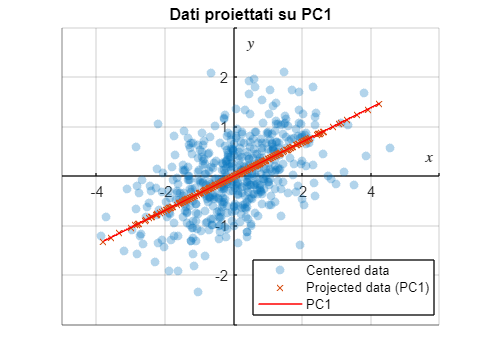

% rappresento i dati
scatter(B(:,1),B(:,2), 'filled', 'MarkerFaceAlpha', alpha,'MarkerEdgeColor','none')
hold on
scatter(projected_B(:,1),projected_B(:,2), 'Marker','x', 'MarkerFaceAlpha', alpha)
plot(projected_B(:,1),projected_B(:,2),'r-','LineWidth',1)
hold off
grid on
legend("Centered data","Projected data (PC1)","PC1",'Location','best')
axis(find_endpoints(projected_B,1))
xlabel("$x$",'Interpreter','latex')
ylabel("$y$",'Interpreter','latex')
title("Dati proiettati su PC1")
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';

## SVD

Vedremo come fare tutto con SVD

## Note

Questo documento è stato generato convertendo in markdown un `MATLAB` livescript utilizzano il tool `livescript2markdown`

% esporto in md
livescript2markdown("pca_v2.mlx","../README.md","AddMention",true,"Format","github")

Coverting latex to markdown is complete
README.md
Note: Related images are saved in README_images


ans = "C:\Users\Dennis Angemi\Documents\GitHub\machine-learning-for-physics\2_principal_component_analysis\README.md"

## Functions

function endpoints = find_endpoints(data_array,margin)
    endpoints = [floor(min(data_array(:,1)))-margin ceil(max(data_array(:,1)))+margin floor(min(data_array(:,2)))-margin ceil(max(data_array(:,2)))+margin];
end